clear;clc;close all
layerfolder='../data/layers/';%route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 9.371173 seconds.


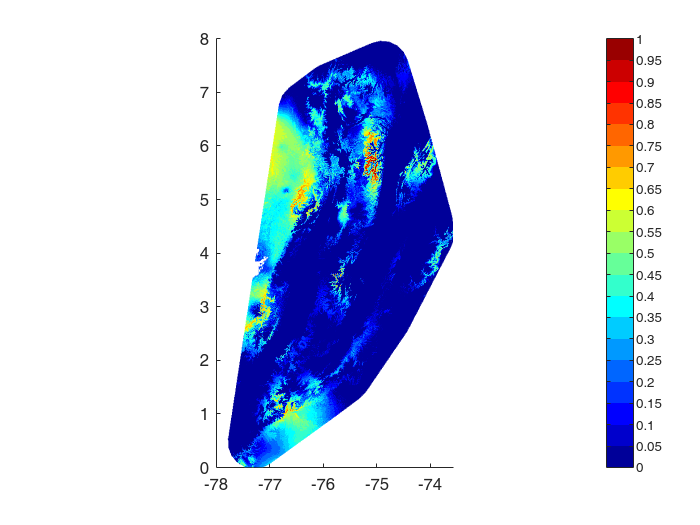

InfoInitialPoint = InitialPoint(Dimensions);
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

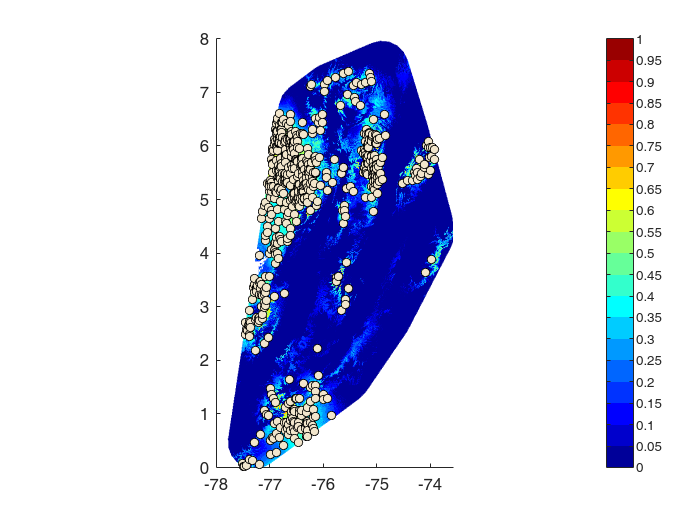

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 600, -3, true, 'GenSP', true, true);

close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, false, false);

----Finding correlation----
Elapsed time is 9.207346 seconds.
----Creating predictors----
¡All done!
Elapsed time is 9.578499 seconds.


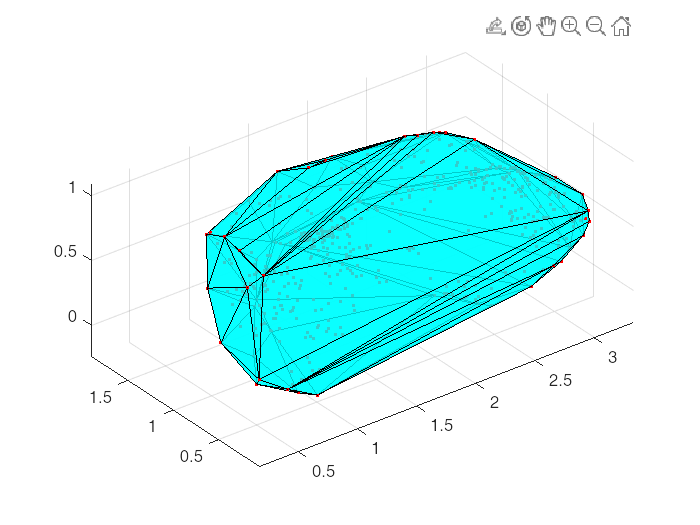

boundPointsIndex =      3
    10
    20
    41
    46
    53
    64
    79
    80
    82


boundPoints =          0         0         0    0.1169    0.1791    0.1656    0.6471    0.1512    0.1233    0.2038    0.2357    0.2250    0.5714    0.6826         0         0    0.2955         0         0
    0.9412    0.9362    0.9521    0.8572    0.6911    0.8867    0.1765    0.6865    0.8695    0.8313    0.7917    0.1000    0.7857    0.2291    0.8724    0.9890    0.0909    0.9316    0.9309
    0.9358    0.9362    0.9415    0.6383    0.4892    0.5926    0.2353    0.5031    0.6143    0.6667    0.6330         0    0.7143    0.3317    0.8571    0.9890    0.0227    0.9263    0.9309
    0.9465    0.9468    0.9574    0.7745    0.5313    0.8170    0.0588    0.5646    0.8258    0.7989    0.7128    0.0500    0.7857    0.2673    0.8673    0.9945    0.0455    0.9368    0.9415
    0.9412    0.9309    0.9521    0.6334    0.4808    0.6209    0.1765    0.4886    0.6401    0.6721    0.6141    0.0250    0.8571    0.2148    0.8571    0.9945         0    0.9316    0.9309
    1.0000    1.0000    1.0000 

radius =     2.8894    3.0454         0    2.3209    2.9419    2.9413    2.7946    2.8266    2.5057    3.0902    2.1446    2.8301    2.7625    2.7550    2.7418    2.4858    0.9205    3.0233    3.1170    2.7931    2.8131    2.8631    3.1087    2.8652    2.8761    2.9584    2.9160    2.7696    2.2976    2.3674    2.7837    2.9077    2.7949    2.8738    2.9948    2.7115    2.6721    3.0403    3.0338    3.0155    3.0165    2.2392    3.0213    3.0336    3.0456    2.8416    3.0338    2.9441    2.9672    3.1430
    0.7055    0.2156    3.0902    1.7581    0.7624    0.7030    0.6134    0.5341    1.4538         0    1.6829    0.9591    0.6036    0.6740    0.6770    1.3375    2.7186    0.7040    0.2135    0.6003    1.0851    0.7116    0.2708    0.8880    0.8686    0.6724    0.5425    0.6433    1.6776    1.7597    1.0943    0.7904    1.1389    0.8881    0.7535    0.7416    0.8223    0.6966    0.6586    0.4067    0.2855    1.5253    0.6898    0.4034    0.3241    0.5772    0.6758    0.6599    0.5613

classifiers =     0.2918    0.2156         0    0.5295    0.2250    0.1918    0.1847    0.2457    0.3508         0    0.4866    0.2727    0.1411    0.2724    0.2797    0.5838    0.4708    0.2281    0.2135         0    0.1474    0.4329    0.2708    0.3744    0.3650    0.1819    0.4021    0.1056    0.5220    0.5392    0.1467    0.2632    0.1520    0.3436    0.1413    0.1948    0.2365    0.1347    0.2232    0.4019         0    0.5212    0.1275    0.4015    0.3241         0    0.1720    0.4268    0.4018    0.2197


newpoints =     0.4399    0.4280    0.4444    0.4768    0.4376    0.4297    0.5992    0.5858    0.6520    0.4804    0.6062    0.6460    0.6589    0.5691    0.3761    0.4740    0.5651    0.4107    0.5918    0.6943    0.7478    0.7660    0.6116    0.4672    0.5309    0.5909    0.6997    0.6741    0.6796    0.6339    0.7127    0.6514    0.5459    0.7848    0.5265    0.6280    0.7970    0.6711    0.5775    0.8060    0.4761    0.7124    0.4556    0.7526    0.4603    0.4767       NaN    0.7528    0.4413    0.6482


ans =     0.3855    0.4104    0.3741    0.3039    0.3946    0.4082    0.1293    0.1383    0.0930    0.2993    0.1293    0.0975    0.0907    0.1701    0.5011    0.3129    0.1746    0.4399    0.1338    0.0794    0.0612    0.0499    0.1247    0.3197    0.2132    0.1338    0.0748    0.0884    0.0884    0.1020    0.0726    0.0930    0.1927    0.0431    0.2200    0.1020    0.0363    0.0884    0.1587    0.0363    0.3084    0.0726    0.3469    0.0612    0.3401    0.3039         0    0.0612    0.3832    0.0952


close all
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=false;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
pcaO(data{1},show,outlier,outlier2)

dataf = bnm_modeling(data, '', true, 4, false);

----Modeling----


ij = 1

-Model 1


close all
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=true;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
data = bnm_modeling2(data{1},show,outlier,outlier2)